# RANSAC Demo

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2018-12-10

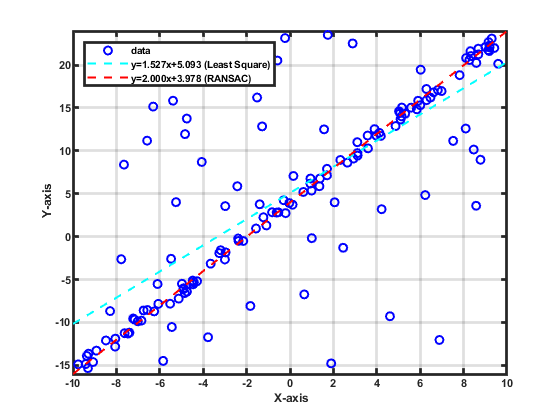

% line fitting (only measurement error)
num_pt = 100;

% line equation y = mx + b;
m = 2;
b = 4;

% x-axis range
xrange = [-10 10];
x = rand(num_pt,1)*(xrange(2)-xrange(1))+xrange(1);

y_true = m*x+b;
y = y_true + (rand([num_pt 1])*2-1);

yrange = m*xrange+b;

% add outlier (50%)
x_out = rand(num_pt*0.5,1)*(xrange(2)-xrange(1))+xrange(1);
y_out = rand(num_pt*0.5,1)*(yrange(2)-yrange(1))+yrange(1);

x_meas = [x;x_out];
y_meas = [y;y_out];

Xmat = [x_meas ones(numel(x_meas),1)];
Ymat = y_meas;
fparam = pinv(Xmat)*Ymat;

param_best = cm_ransac_line(x_meas, y_meas, 1, 1000);

figure(1)
plot(x_meas, y_meas, 'ob', 'linewidth', 1.5);
line(xrange,fparam(1)*xrange + fparam(2), 'Color', 'c', 'linewidth',  1.5, 'LineStyle', '--');
line(xrange,param_best(1)*xrange + param_best(2), 'Color', 'r', 'linewidth',  1.5, 'LineStyle', '--');

legend({'data', ...
    strcat('y=',sprintf('%3.3f',fparam(1)),'x+',sprintf('%3.3f',fparam(2)) , ' (Least Square)'), ...
    strcat('y=',sprintf('%3.3f',param_best(1)),'x+',sprintf('%3.3f',param_best(2)) , ' (RANSAC)'), ...
    },'location','northwest')
axis tight;grid on; hold off
xlabel('\bf X-axis');xlim(xrange);
ylabel('\bf Y-axis');
set(gca,'FontSize',8,'linewidth',2,'fontweight','bold')